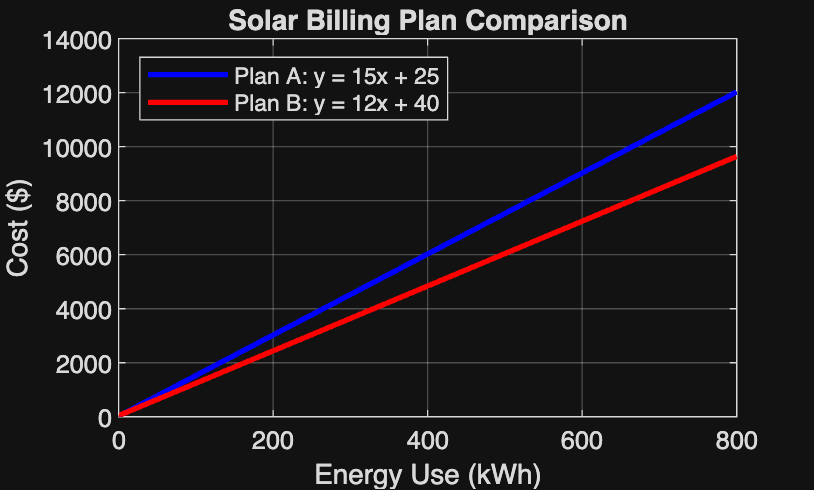

%{
ES115 - Control Panel Class Project
Author: Nivea Williamson
Version: 1.0
Date: 2026-03-26

Purpose:
    Compare two solar billing plans by graphing their cost equations
    and displaying a table of values for selected energy usage amounts.

Input:
    - Energy usage values in kWh
    - Plan A cost equation: y1 = 15x + 25
    - Plan B cost equation: y2 = 12x + 40

Output:
    - Graph of both billing plans
    - Table comparing the cost of both plans

Engineering Algorithms:
    - Create a row vector of x-values for energy usage
    - Compute cost for both billing plans using linear equations
    - Plot both plans on the same graph
    - Create a column vector of selected usage values
    - Compute corresponding bill amounts
    - Display results in table form

MATLAB Tools/Functions:
    - plot()
    - title()
    - xlabel()
    - ylabel()
    - legend()
    - grid on
    - hold on
    - table()
    - disp()
%}

%% PROJECT 1

clc;
clear;

% Create row vector from 0 to 800 in steps of 25
x = 0:25:800;

% Compute linear expressions for the cost vs. x
y1 = 15*x + 25;   % Plan A
y2 = 12*x + 40;   % Plan B

% Plot both billing plans
plot(x, y1, 'b-', 'LineWidth', 2)
hold on;
plot(x, y2, 'r-', 'LineWidth', 2)

title("Solar Billing Plan Comparison")
xlabel("Energy Use (kWh)")
ylabel("Cost ($)")
legend("Plan A: y = 15x + 25", "Plan B: y = 12x + 40", "Location", "northwest")
grid on;


% Usage values from 0 to 60 in steps of 5
usage = (0:5:60)';

% Compute corresponding bill costs
bill_y1 = 15*usage + 25;
bill_y2 = 12*usage + 40;

% Create table comparing both plans
T = table(usage, bill_y1, bill_y2, ...
    'VariableNames', {'Usage_kWh', 'PlanA_Cost', 'PlanB_Cost'});

% Display table
disp(T);

    Usage_kWh    PlanA_Cost    PlanB_Cost
    _________    __________    __________

        0            25            40    
        5           100           100    
       10           175           160    
       15           250           220    
       20           325           280    
       25           400           340    
       30           475           400    
       35           550           460    
       40           625           520    
       45           700           580    
       50           775           640    
       55           850           700    
       60           925           760    

